# Sapphire Quick Look

## Setup

addpath(genpath("C:\Users\00011114\Documents\MATLAB"));
addpath(genpath("C:\Users\00011114\Documents\ArduinoMatlab"));
addpath("C\Users\00011114\Documents\SapphireMini\Matlab\mseedlib");

clear variables
[file,path]=uigetfile(".msd","Select miniseed input file",'MultiSelect',"on");
fname = fullfile(path,file);
samprate = 16;

Cat the miniseed blocks together to build the structure

X=[];
if(strcmp(class(fname),'char'))
    fname = {fname};
end

for k=1:length(fname)
    d = dir(fname{k});
    if(d.bytes > 0)
        fprintf("Loading %s\n",fname{k})
        try
            XX=rdmseed(fname{k});
        catch
            fprintf("Error on rdmseed read for %s\n",fname{k});
        end
        indx_zero = [XX.NumberSamples]==0;
        XX(indx_zero)=[];
        X = cat(2,X,XX);
        ftime(k) = XX(1).t(1);
    end
end

Loading F:\S098_220101_N001.msd
Loading F:\S098_220914_N001.msd


Error on rdmseed read for F:\S098_220914_N001.msd


Loading F:\S098_220915_N001.msd


This section extracted from rdmseed to build the index blocks

un = unique(cellstr(char(X.ChannelFullName)));
nc = numel(un);
for i = 1:nc
    k = find(strcmp(cellstr(char(X.ChannelFullName)),un{i}));
    I(i).ChannelFullName = X(k(1)).ChannelFullName;
    I(i).XBlockIndex = k;
    I(i).ClockDrift = ([diff(cat(1,X(k).RecordStartTimeMATLAB));NaN]*86400 - cat(1,X(k).NumberSamples)./cat(1,X(k).SampleRate))./cat(1,X(k).NumberSamples);
    I(i).OverlapBlockIndex = k(find(I(i).ClockDrift.*cat(1,X(k).NumberSamples).*cat(1,X(k).SampleRate) < -.5) + 1);
    I(i).OverlapTime = cat(1,X(I(i).OverlapBlockIndex).RecordStartTimeMATLAB);
    I(i).GapBlockIndex = k(find(I(i).ClockDrift.*cat(1,X(k).NumberSamples).*cat(1,X(k).SampleRate) > .5) + 1);
    I(i).GapTime = cat(1,X(I(i).GapBlockIndex).RecordStartTimeMATLAB);
end
BDFIndx = find(~cellfun(@isempty,strfind({I.ChannelFullName},'BDF')));
samprate = X(I(BDFIndx).XBlockIndex(1)).SampleRate

samprate = 128

check for missing samples

for k=1:(nc-1)
    xindx = I(k).XBlockIndex;
    nsamples = [X(xindx).NumberSamples]';
    tstart= reshape([X(xindx).RecordStartTimeISO],22,[])';
    tstartd = datetime(tstart,'InputFormat','uuuu-DDD HH:mm:ss.SSSS');
    clockDrift{k} = I(k).ClockDrift;
    badtimes = find(tstartd<datetime('02/02/2022','InputFormat','MM/dd/uuuu'));
    if(~isempty(badtimes))
        badtimes(end+1) = 1 + badtimes(end);
        tstartd(badtimes) = [];
        nsamples(badtimes)= [];
        clockDrift{k}(badtimes) = [];
    end
    deltaSamps{k} = nsamples(1:end-1) - round(samprate*seconds(diff(tstartd)));
end
minElements = min(cellfun(@length,deltaSamps));
if(any(cellfun(@any,deltaSamps)))
    warning("Sample Time Jumps!!");
else
    fprintf("Sample Time is continuous");
end

OK, now load the data.  This will be all the channels except the logIndex channel

clear NumSamples TimeCorrection DataQuality x t ix
logIndx = find(~cellfun(@isempty,strfind({I.ChannelFullName},'LOG')));
minsamps = inf;
for k=1:length(I)
    if(k == logIndx)
        continue;
    end
    ix = I(k).XBlockIndex;
    fprintf("Channel: %s\n",I(k).ChannelFullName)
    seqNum = str2num(char(X(ix).SequenceNumber));
    NumSamples{k}     = [X(ix).NumberSamples];
    TimeCorrection{k} = [X(ix).TimeCorrection];
    DataQuality{k}    = [X(ix).DataQualityFlags];
    xx{k}                  = cat(1,X(ix).d);
    tt{k}                  = cat(1,X(ix).t);
    nsamps = size(xx{k},1);
    minsamps = min(minsamps,nsamps);
end

Channel: ZZ:SM098:00:BDE
Channel: ZZ:SM098:00:BDF


if(exist('xx')==0)
    fprintf("NO DATA FRAMES!!")
    return;
end
for k=1:length(xx)
    xx{k}=xx{k}(1:minsamps);
    tt{k}=tt{k}(1:minsamps);
end

t = cat(2,tt{:});
x = cat(2,xx{:});

There is a bug in the logging code that sometimes screws up the log strings.  This can also happen if multiple files from different runs are concatenated.  We parse the JSON strings one at a time and discard any that are damaged.

logIndx = find(~cellfun(@isempty,strfind({I.ChannelFullName},'LOG')));
if(isempty(logIndx))
    warning("No Log Files");
else
    clear power gps dlhr bmp acc C corrupted 
    lowDate = posixtime(datetime('12/31/2021','InputFormat','MM/dd/uuuu'));
    ix = I(logIndx).XBlockIndex;
    logtext = cat(2,X(ix(1:end)).d);
    logtext = erase(logtext,char(0)); %drop the null pad
    logtext = ['}' logtext '{'];            %fake the end braces so the split works
    %[C,matches] = strsplit(logtext,{'}{'});  // use for old versions
    [C,matches] = strsplit(logtext,'}{');
    prevTime = 0;
    badTimes = 0;
    badDiff = [];
    for k=1:length(C)
        str = C{k};
        if(isempty(str))
            continue;
        end
        jsonstr = ['{' str '}'];        %restore the {} stripped by parser
        % jsonstr = strrep(jsonstr,"i:",'"i":'); %Fix
        corrupted(k)=false;
        try
            z= jsondecode(jsonstr);
        catch
            corrupted(k)=true;
        end
        if(~corrupted(k))
            f1 = fieldnames(z);
            try
                curTime(k) = getfield(z,f1{1},'Time');
                if((curTime(k)>1e10)  )%| (curTime(k)<lowDate))
                    badTimes = 1+badTimes;
                    badDiff(badTimes) = k;
                else
                    prevTime = curTime(k);
                    
                    switch(f1{1})
                        case 'power'
                            icnt = z.power.i;
                            power(icnt) = z.power;
                            
                        case 'gps'
                            icnt = z.gps.i;
                            gps(icnt)   = z.gps;
                            
                        case 'DLHR'
                            dlhr    = z.DLHR;
                        case 'BMP'
                            bmp     = z.BMP;
                        case 'ACC'
                            acc     = z.ACC;
                        otherwise
                            error('Unknow JSON in log file');
                    end
                end
            catch
            end
        end
    end
    
    if(badTimes>0)
        warning("There are bad times in the log file");
        fprintf('%d times that go backwards',badTimes);
    end
    if(sum(corrupted)>0)
        warning("There are corrupted JSON strings in the log file");
        fprintf('%d corrupted strings\n',sum(corrupted));
        fprintf('Sample: %s\n',[C{find(corrupted,1)} '}}']);
    end
end

1 corrupted strings


Sample: "gps":{"Time":1663200{}}


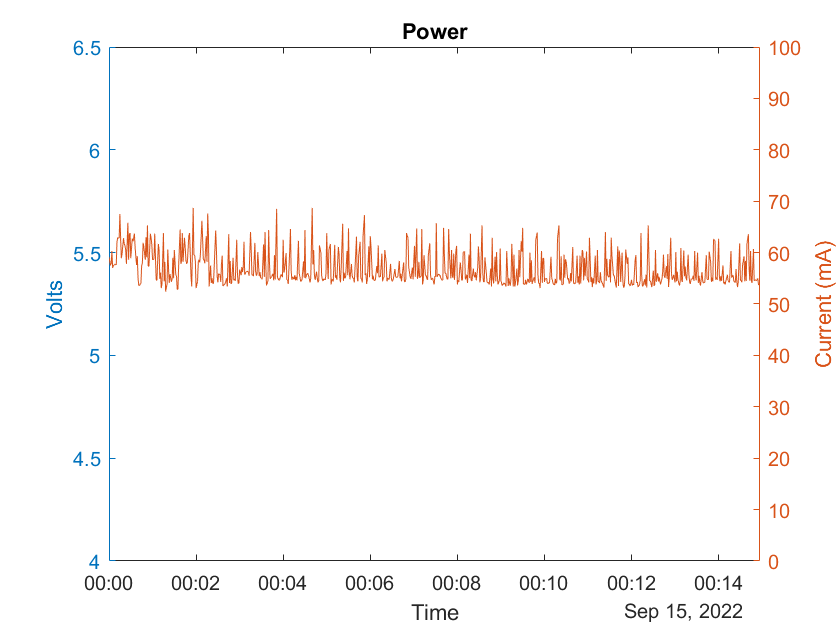

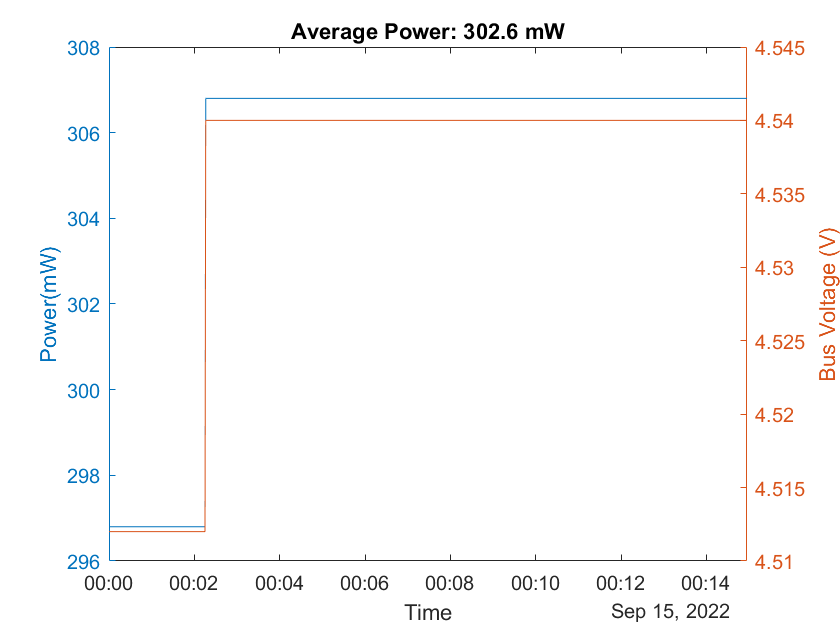

% power system power
if(~isempty(logIndx))
    figure
    powerTime = datetime([power.Time],'convertFrom','posixtime');
    indx = find(powerTime > datetime('01-Feb-2022 00:00:00'));
    
    yyaxis left
    plot(powerTime,[power.batVolt])
    title('Power')
    xlabel('Time');
    ylabel('Volts')
    ylim([4 6.5])
    yyaxis right
    plot(powerTime,[power.current_mA]);
    ylim([0 100])
    ylabel('Current (mA)');
   xlim([powerTime(indx(1)) powerTime(indx(end))])
    % calculate power use
    figure
    yyaxis left
    power_mW = [power.power_mW];
    plot(powerTime,power_mW);
    xlabel('Time');
    ylabel('Power(mW)');
    title('Power Use')
   xlim([powerTime(indx(1)) powerTime(indx(end))])
    yyaxis right
    plot(powerTime,[power.busVoltage_V]);
    ylabel('Bus Voltage (V)')
    
    deltaT = diff(powerTime);
    deltaT(deltaT>seconds(1000)) = 0;   %clip off anything too long
    
    energy = sum(power_mW(1:end-1) .* seconds(deltaT)) / sum(seconds(deltaT));
    title(sprintf('Average Power: %.1f mW',energy));
end

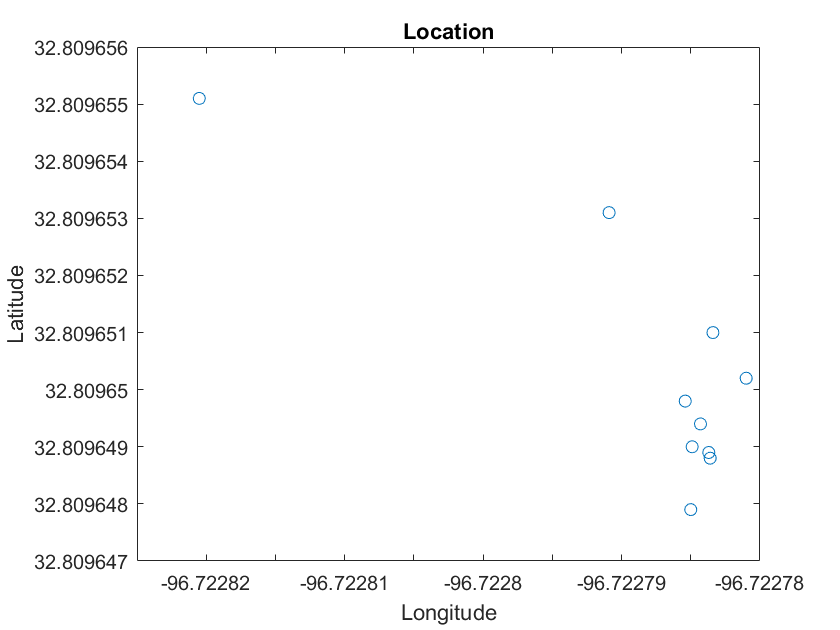

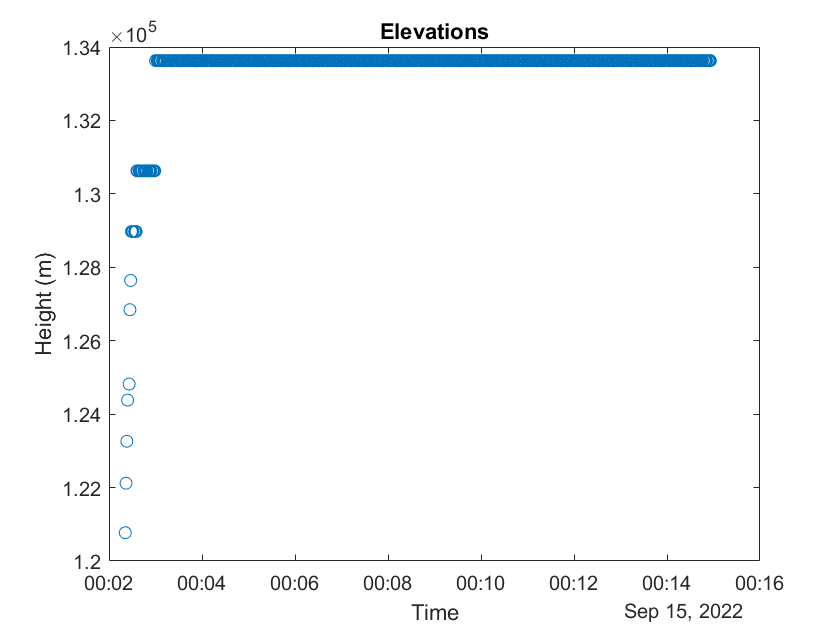

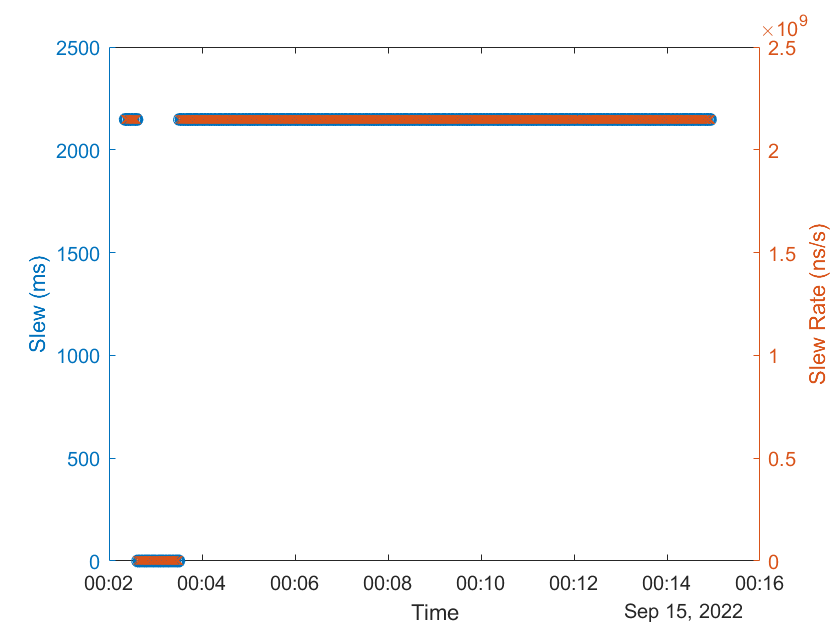

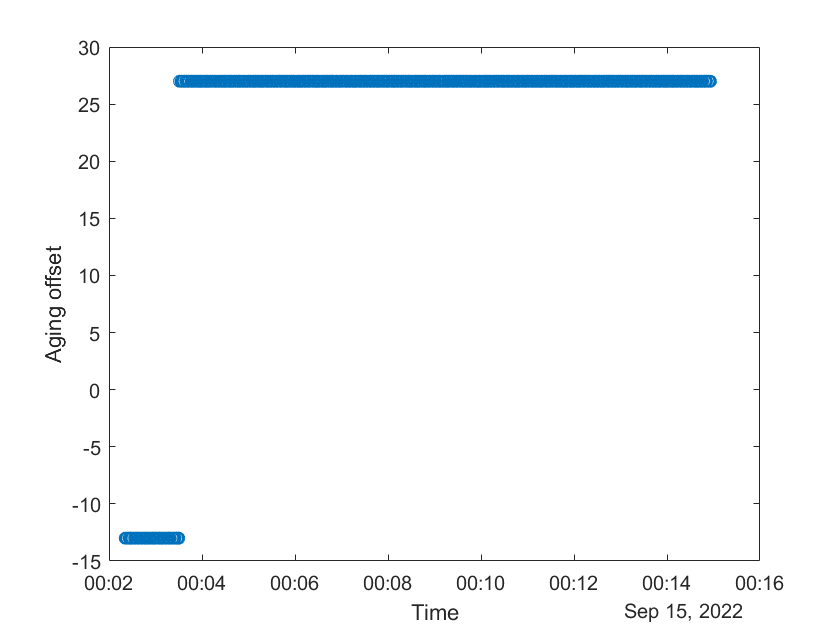

GPS running for 2.5701e+02 days


ans = 6.2326e-05

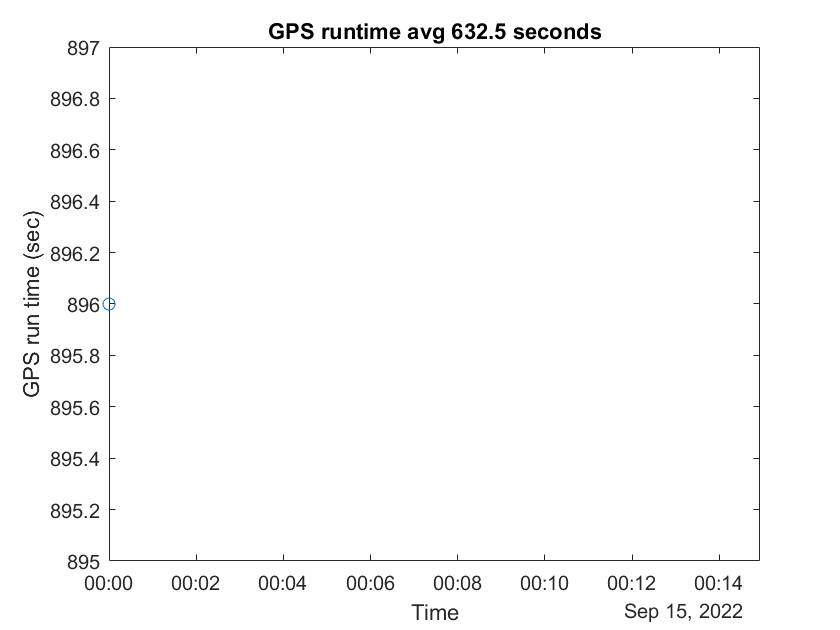

%We need a GPS plot here, but so far don't have data with a lock
if(~isempty(logIndx))
    gpsnotnull = gps.Time;
    gpsTime = datetime([gps.Time],'convertFrom','posixtime');
    indx    = find(gpsTime > datetime('01-Feb-2022 00:00:00'));
    goodtimes = gpsTime(indx([1 end]));
    lat = [gps.Lat];
    lon = [gps.Lon];
    slew= [gps.Slew];
    slewrate = [gps.SlewRate];
    aging = [gps.Aging];
    height = [gps.Height];
    gpsgood = find((lat~=0) & (lon~=0) & (gpsTime>datetime('01-Feb-2022 00:00:00')));
    lat = lat(gpsgood);
    lon = lon(gpsgood);
    height = height(gpsgood);
    slew = slew(gpsgood);
    slewrate = slewrate(gpsgood);
    aging = aging(gpsgood);
    gpstimes = gpsTime(gpsgood);
    figure
    
    plot(lon/1e7,lat/1e7,'o')
    title('Location');
    xlabel('Longitude');
    ylabel('Latitude');
    
    figure
    plot(gpstimes,height,'o');
    title('Elevations');
    xlabel('Time');
    ylabel('Height (m)')
    
    figure
    yyaxis left
    plot(gpstimes,slew/1e6,'o');
    ylabel('Slew (ms)')
    yyaxis right
    plot(gpstimes,slewrate,'x');
    ylabel('Slew Rate (ns/s)')
    xlabel('Time')
    
    figure
    plot(gpstimes,aging,'o');
    ylabel('Aging offset');
    xlabel('Time')
    
    gTimes = [gps.Time];
    gonTime = [gps.OnTime];
    runDays = (gTimes(end)-gTimes(1))/86400;
    fprintf("GPS running for %.4d days\n",runDays);
    
    gstart = find(diff([0 gTimes])>60);
    gend   = [gstart(2:end) length(gTimes)];
    grunTime = gonTime(gend) - gonTime(gstart);
    gonTime(end)/(gTimes(end)-gTimes(1))
    
    figure
    plot(datetime(gTimes(gstart),'convertfrom','posixtime'),grunTime,'o');
    ylabel('GPS run time (sec)');
    xlabel('Time')
    title(sprintf('GPS runtime avg %0.1f seconds',mean(grunTime)))
    xlim(goodtimes)
end

%plot the data
figure
chanNames = unique({I.ChannelFullName});
chans = char(chanNames');
chans = chans(:,end-2:end);
sampleTime = datetime(t,'ConvertFrom','datenum');
% goodtimes = find(sampleTime(:,1) > datetime('01-Feb-2022 00:00:00'));
% goodtimes = sampleTime(goodtimes([1 end]),1);
missingSamps = x==-128;
xp = x;
xp(missingSamps) = NaN;   %clean up the missing samples
bdfchan = find(cellfun(@isempty,(strfind(cellstr(chans),'BDF')))==0);
bdkchan = find(cellfun(@isempty,(strfind(cellstr(chans),'BDK')))==0);
bdlchan = find(cellfun(@isempty,(strfind(cellstr(chans),'BDL')))==0);
bdechan = find(cellfun(@isempty,(strfind(cellstr(chans),'BDE')))==0);
bhzchan = find(cellfun(@isempty,(strfind(cellstr(chans),'BHZ')))==0);

## Plot the temperature data if it exists

figure
if(~isempty(bdkchan))
    plot(sampleTime(:,bdkchan),xp(:,bdkchan));
    missSum = sum(missingSamps(:,bdkchan));
    hold on;
end
if(~isempty(bdlchan))
    plot(sampleTime(:,bdlchan),xp(:,bdlchan));
    missSum = sum(missingSamps(:,bdkchan));
end
if(~isempty(bdkchan)&&~isempty(bdlchan))
    v = ylim;
    %plot(datetime([ftime;ftime],'ConvertFrom','datenum'),repmat(v',1,length(ftime)),'--r');
    % if(sum(missingSamps(:,3))>0)
    %     plot(sampleTime(find(missingSamps(:,3))),20,'rx');
    % end
    % if(sum(missingSamps(:,4))>0)
    %     plot(sampleTime(find(missingSamps(:,4))),21,'ro');
    % end
    hold off;
    if(~isempty(bdkchan) && ~isempty(bdlchan))
        legend('BDK','BDL');
    end
    xlabel('Time')
    ylabel('Temperature (degC)')
    set(gca,'XTickLabelRotation',45);
    if(missSum==0)
        fprintf("No missing samples!")
    else
        fprintf('All Channels: %d missing samples\n',missSum);
        fprintf(' Missed sample rate: %.2f per 10000 samples',10000*missSum/length(x));
        fprintf(' Missed sample rate 1 sample/%.1f minute',length(x)/samprate/missSum);
    end
    if(~isempty(bdkchan))
        fprintf('BDK: %d overrange samples\n',sum(isnan(x(:,bdkchan))))
    end
    xlim(goodtimes);
end

## plot the pressure data

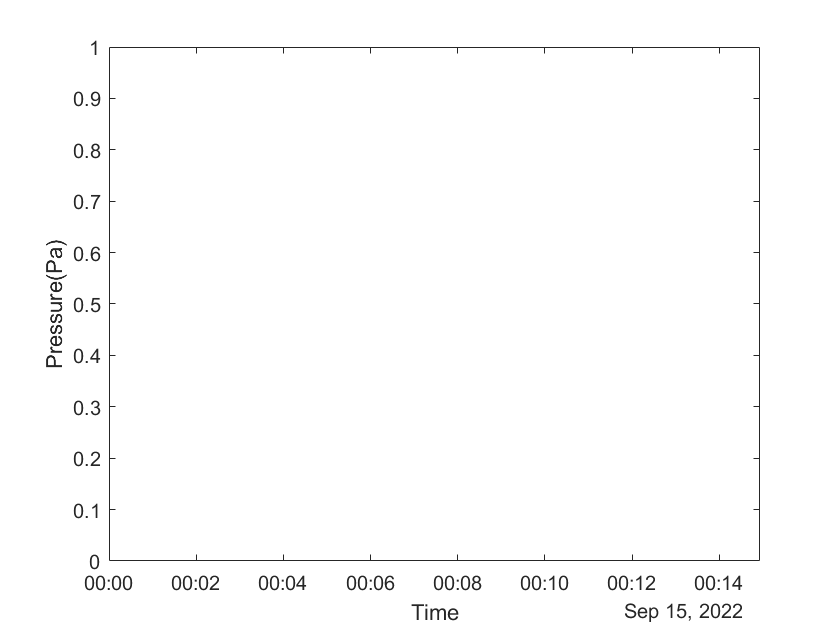

figure
if(~isempty(bdfchan))
    plot(sampleTime(:,bdfchan),xp(:,bdfchan));
    xlabel('Time');
    ylabel('Pressure(Pa)')
    xlim(goodtimes);
end

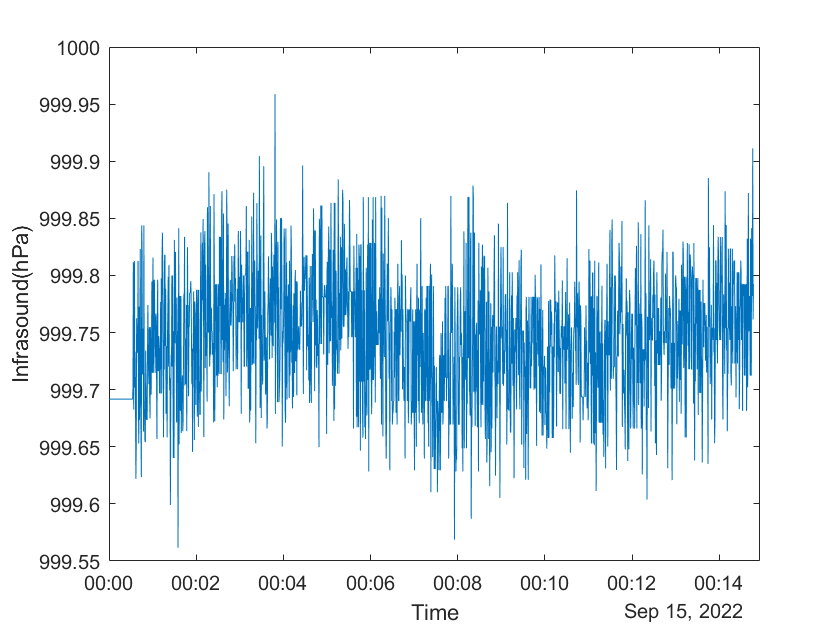


if(~isempty(bdechan))
    xnan = isnan(x(:,bdechan))*100;
    xnan(xnan==0) = NaN;
    xnan(xnan==100) = 0;
    figure
    h=plot(sampleTime(:,bdechan),[xp(:,bdechan) xnan]);
    set(h(2),'LineWidth',4)
    xlabel('Time');
    ylabel('Infrasound(hPa)')
    xlim(goodtimes);
end

## Overall spectrum of Infrasound (for noise analysis)

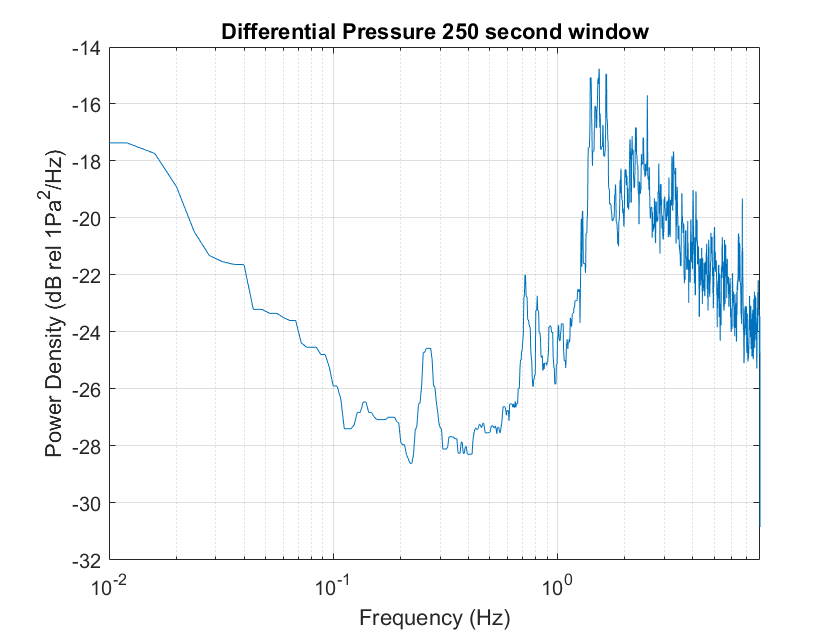

indx = find(sampleTime(:,bdfchan)>goodtimes(1) & sampleTime(:,bdfchan)<goodtimes(2));

npeaks = 15;

wlen = samprate*250;
xpf = xp;
xpf(isnan(xp)) = 0;
xpf = medfilt1(xpf,3,'omitnan');
xpf(~isnan(xp)) = xp(~isnan(xp));
xpf = xpf(indx,:);
sampleTimeGood = sampleTime(indx,:);

[Pxx,F] = pwelch(detrend(double(xpf(:,bdfchan))),wlen,9*wlen/10,wlen,samprate);
figure
semilogx(F,10*log10(medfilt1(Pxx,7,'zeropad')));
grid on;
title('Differential Pressure 250 second window');
ylabel('Power Density (dB rel 1Pa^2/Hz)');
xlabel('Frequency (Hz)');
xlim([0.01 samprate/2])

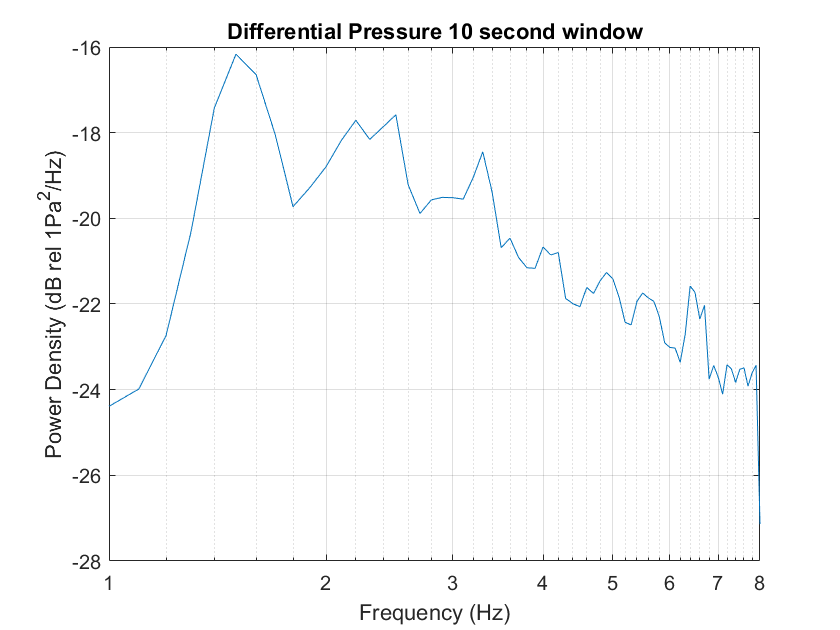


wlen = samprate*10;
[Pxx,F] = pwelch(detrend(double(xpf(:,bdfchan))),wlen,wlen/2,wlen,samprate);
figure
semilogx(F,10*log10(Pxx));
xlim([ 1 samprate/2]);
grid on;
title('Differential Pressure 10 second window');
ylabel('Power Density (dB rel 1Pa^2/Hz)');
xlabel('Frequency (Hz)');

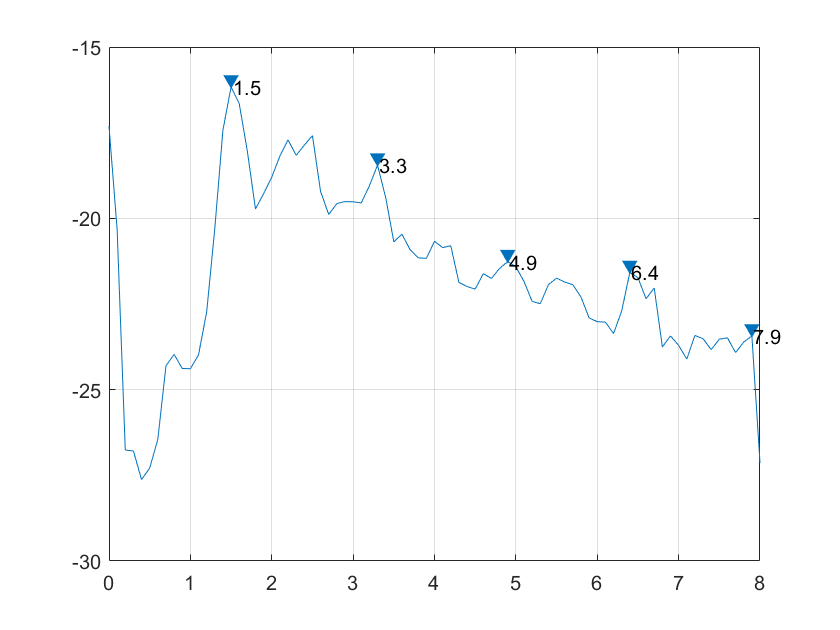

%ylim([-48 -30])

figure
[pks,locs] = findpeaks(10*log10(Pxx),F,'NPeaks',npeaks,'MinPeakDistance',1,'SortStr','descend');
findpeaks(10*log10(Pxx),F,'NPeaks',npeaks,'MinPeakDistance',1,'SortStr','descend');
text(locs+0.02,pks,num2str(locs));
grid on

%ylim([-48 -30])

##  Spectrogram for check of periodic noise

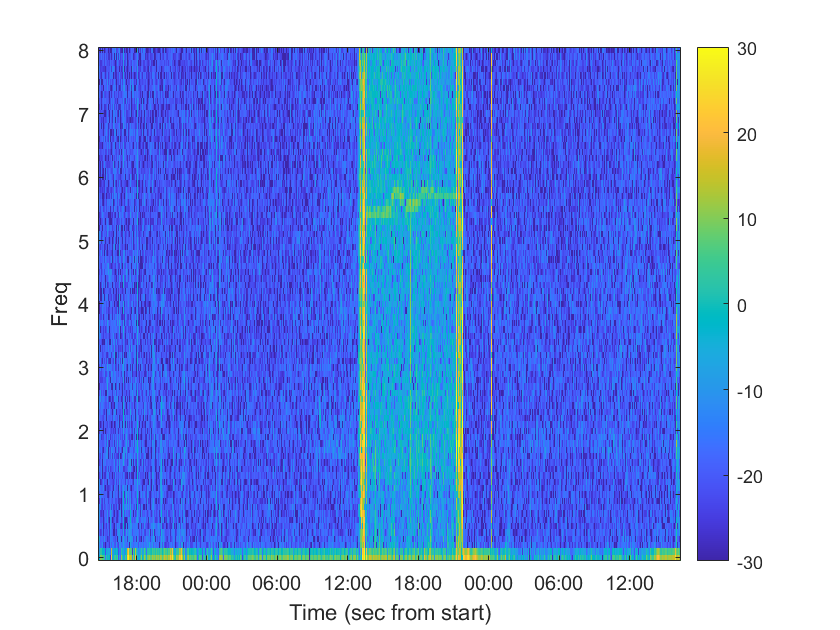

wlen = samprate*10;
[S,F,T] = spectrogram(detrend(double(xpf(:,bdfchan))),wlen,wlen/2,wlen,samprate);

figure
imagesc(datenum(sampleTimeGood(:,bdfchan)),F,20*log10(abs(S)));
set(gca,'CLim',[-30 30]);
colorbar;
xlabel('Time (sec from start)');
ylabel('Freq');
set(gca,'YDir','normal')
datetick('keeplimits')

for k=1:5
    beep
    pause(5)
end

## PPS analysis if GPS is putting PPS on all channels

return;

Look for 1pps from GPS

win = hamming(samprate*10);
hop = samprate;
fs = samprate;
refchan = 3;
[C, q, t2] = cepstrogram(x(:,refchan), win, hop, fs);
[~,cindx] = min(abs(q-1));
figure
plot(t2/60,abs(C(cindx,:)));
title("Cepstral 1 second pps");
xlabel("Time from start (min)")'
ylabel("abs(C) @ 1 second)");
grid on;
C(cindx,isinf(C(cindx,:)))=0;
ppsSegs = abs(C(cindx,:))' > 0.5;
ppsSegd = diff([0;ppsSegs]);
ppsStart = find(ppsSegd>0.5);
ppsEnd   = find(ppsSegd<-0.5);
nsegs    = min(length(ppsStart),length(ppsEnd));
ppsSegI  = [ppsStart(1:nsegs) ppsEnd(1:nsegs)];

ppsWins  = ppsSegI*hop;
ppsnSegs = diff(ppsSegI');

Check each channel for delta offset from adjacent channels


for seg = 1:size(ppsWins,1);
    tstart = t(ppsWins(seg,1),refchan);
    tend   = t(ppsWins(seg,2),refchan);
    sampdelta = round(samprate*86400*(t(ppsWins(seg,1),refchan)-t(ppsWins(seg,1),:)));
    tindx = ppsWins(seg,1):ppsWins(seg,2)-1;
    tseg = t(tindx,refchan);
    tfrac = abs(tseg*86400 - round(tseg*86400));
    [~,zindx] = min(tfrac); %find the offset to a second
    zindx = mod(zindx-1,samprate); %get it back to the first offset
    xr = reshape(x(tindx,refchan),samprate,ppsnSegs(seg));
    npts(seg) = median(sum(xr<0));
    onepulse = ones(samprate,1);
    pindx = mod((1:npts(seg))+zindx-1,samprate)+1;
    onepulse(pindx) = -1;
    segpulse = repmat(onepulse,ppsnSegs(seg),1);
    
    for chan=1:4
        xr = reshape(x(sampdelta(chan)+tindx,chan),samprate,ppsnSegs(seg));
        xc(:,chan,seg) = xcorr(segpulse,x(sampdelta(chan)+tindx,chan),samprate/2,'coeff');
        [~,xcm(chan,seg)] = max(abs(xc(:,chan,seg)));
        clf;plot(onepulse*500);hold on;plot(xr);hold off;drawnow;
    end
end
figure
plot(xcm');
xlabel("GPS segment");
ylabel('Delta Shift');
legend('BDF','BDE','BDK','BDL')